% Syntax: Baltic_seadatanet_BEC_analyses.m (script)
%
% Description
% Analyses of SeaDataNet data as provided by BEC.
%
%
% 
%
% Input: matlab files created from the original .csv files
%
% Baltic Study [2011-2013]:
% *[1] 
% *[2] 
% *[3]
%
% Data source:
% BEC products for validation
%
%
% current version: v1r0 (2020/01/20)
%
% History
% -
% Version: v1r0
%
%
% =========================================================================
%
% Author: rcatany
%
% =========================================================================

clc; clear;
close all

% Get SSS-satellite data within a given distance from each Argo float
r = 25; % Radius distance from reference point (in Km)

ibasin = 9; % Baltic Sea [9];
[xmin,xmax,ymin,ymax,basin_str] = map_lim_raf (ibasin);

fg_save = 1; % flag save figures [1]; or not [0];
fg_format = 'png';

path_root = ('/Volumes/Rogue/Data/');
folder_data = ([path_root ...
    'SSS/Baltic/BEC/Validation/indata/SeaDataNet/']);


% Make a log_file to record status of each ARGO-BEC file [2020/01/21]
folder_log = '/Volumes/Rogue/Data/SSS/Baltic/BEC/Validation/indata/';
fn_log = [folder_log 'SDN_MISSING_20200121.txt'];

folder_figs = ['/Volumes/Rogue/scratch/Validation/SeaDataNet/'];

filename = [folder_data 'data_from_SDN_2015-09_TS_BalticSea_QC_done_v2_filtered.nc'];

iyear = 2013;

imonth = 1:12;

% SMOS-data missing Jan-2011. <TO ask to BEC to clear data>
if iyear == 2012 
    imonth = 2:12;
end

## [1] Colocation Argo-2-Satellite

run Baltic_SDN_BEC_colocations.m % (snippet)

## [1.1] Compute Argo at 10 m and the Argo average surface-2-10m

nprof = length(time_irange);

no_nan = any(isnan(time_irange));

if no_nan == 1    
    error(['there cannot be NaN in time_range. '...
        'If there are you need to define nprof as a '...
        'function of lon_irange, lat_irange']);
end

[zlevels,~] = size(PRES_intp);

SALT10_mean = nan(1,nprof);
SALT10_std = nan(1,nprof);
SALT10_point = nan(1,nprof);

for nn = 1:nprof
    %index the average top 10m and find the value at 10m
    ind_mean = find(PRES_intp(:,nn)<=30,zlevels,'first');
    ind_point = find(PRES_intp(:,nn)==10,zlevels,'first');
    
    SALT_beta = SALT_intp(ind_mean,nn);
    SALT10_mean(1,nn) = nanmean(SALT_beta);
    SALT10_std (1,nn) = nanstd(SALT_beta);
    
    SALT10_point_beta = SALT_intp(ind_point,nn);
    
    while isnan(SALT10_point_beta) & PRES_intp(ind_point+1,nn) < 30
        ind_point = ind_point+1;
        SALT10_point_beta = SALT_intp(ind_point,nn);
    end
    
    ind_point = find(PRES_intp(:,nn)==10,zlevels,'first'); % reset index to continue search upwards
    
    while isnan(SALT10_point_beta) & PRES_intp(ind_point,nn) >= 5 
        ind_point = ind_point-1;
        SALT10_point_beta = SALT_intp(ind_point,nn);
        
    end
    
    if isnan(SALT10_point_beta)
        SALT10_point_beta = NaN; % [FLAG] Profile with no measurements at surface
    end
    
    SALT10_point(1,nn) = SALT10_point_beta;
    
end; clear nn *beta*

## [2] Get SDN within a searching distance at each study region

Get SDNwithin a given distance from the center if SREG.

r = 200; % km

% load study regions
[lon_sreg, lat_sreg, SREG_str1, SREG_str2,ColorMarker_sreg] = Baltic_studyregion;

[a,b,c] = size(SALT_intp);

% number of study region
Nsreg = length(lon_sreg);

% convert platform_type to cell array (ie. to easy the reading)

A = cell(size(platform_type_irange));

for nn = 1:length(A)
    A{nn} = platform_type_irange(nn);
    
    
end; clear nn

platform_type_irange = A; clear A;

% Pre-locate variables

TT = nan([a,b, Nsreg]);
SALT_sreg_irange = TT;
TEMP_sreg_irange = TT;
PRES_sreg_irange = TT; clear TT

lon_sreg_irange = nan(b,Nsreg);
lat_sreg_irange = nan(b,Nsreg);
time_sreg_irange = nan(b,Nsreg);
platform_type_sreg_irange = cell(b,Nsreg);

SALT10_mean_sreg_irange = nan(b,Nsreg);
SALT10_std_sreg_irange = nan(b,Nsreg);
SALT10_point_sreg_irange = nan(b,Nsreg);


for nn = 1:length(lon_sreg)
    DIST = Distance(lon_sreg(nn),lat_sreg(nn),lon_irange,lat_irange);
    
    irange = find(DIST <= r);
    Ln = length(irange);
    
    if Ln >0
    lon_sreg_irange(1:Ln,nn) = lon_irange(irange);
    lat_sreg_irange(1:Ln,nn) = lat_irange(irange);
    time_sreg_irange(1:Ln,nn) = time_irange(irange);
    platform_type_sreg_irange (1:Ln,nn) = platform_type_irange(irange);
    
    
    SALT_sreg_irange(:,1:Ln,nn) = SALT_intp(:,irange);
    TEMP_sreg_irange(:,1:Ln,nn) = TEMP_intp(:,irange);
    PRES_sreg_irange(:,1:Ln,nn) = PRES_intp(:,irange);
    
    SALT10_mean_sreg_irange(1:Ln,nn) = SALT10_mean(irange);
    SALT10_std_sreg_irange(1:Ln,nn) = SALT10_std(irange);
    SALT10_point_sreg_irange(1:Ln,nn) = SALT10_point(irange);
    
    end
    
end

## [1] Plot SDN stations

## [1.1] Plot ALL SDN Stations

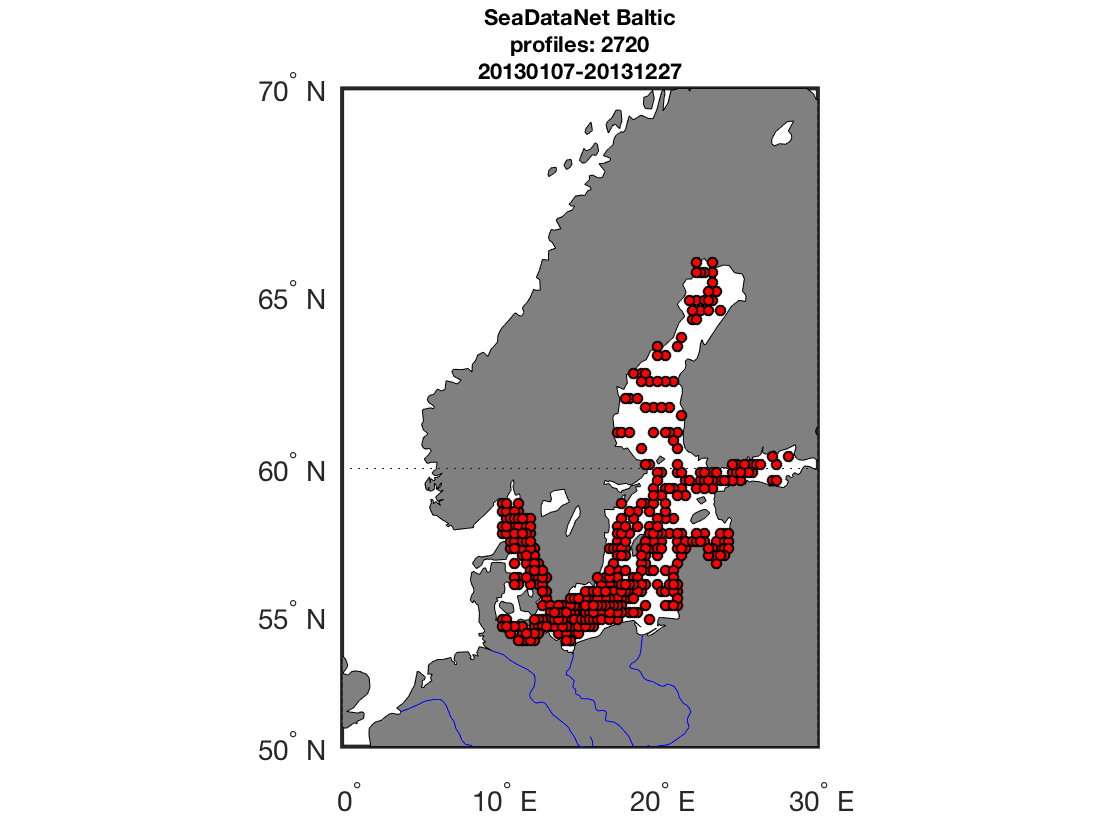

time1 = nanmin(time_irange(:));
time2 = nanmax(time_irange(:));

time_str1 = datestr(time1,'yyyymmdd');
time_str2 = datestr(time2,'yyyymmdd');

nprof = sum ((~isnan(lon_irange)) & (~isnan(lat_irange)));

% ========================

figure
h1 = plot_map_SDN_BEC(lon_irange,lat_irange);

title({...
    ['SeaDataNet ' basin_str];...
    ['profiles: ' num2str(nprof)]
    [time_str1 '-' time_str2]},'fontsize',24);



% Save figure  - output -
fg_name = ['SDN_MAP_ALL_' time_str1 '_' time_str2 '.' fg_format];

% Save figure  - output -
folder_this = [folder_figs 'MAPS/'];

if fg_save == 1
    foldercheck_raf(folder_this); %! make folder_figs
end

fg_name = [folder_this fg_name];

% check fn existence
fg_exist = exist(fg_name,'file');
if fg_save == 1 && fg_exist == 0
    save_raf(gcf,fg_name,fg_format); close
end

## [1.2] Plot REGIONAL SDN Stations

time1 = nanmin(time_sreg_irange(:));
time2 = nanmax(time_sreg_irange(:));

time_str1 = datestr(time1,'yyyymmdd');
time_str2 = datestr(time2,'yyyymmdd');


nprof = sum ((~isnan(lon_sreg_irange(:))) & (~isnan(lat_sreg_irange(:))));


% ========================
figure
% set map axes
lon_step = 10;
lat_step = 5;

map_projection ='merc';
fillmap_super(map_projection,...
    xmin,xmax,ymin,...
    ymax,lon_step,lat_step);
hold on


for nn = 1:length(SREG_str1)
    nprof_sreg (nn) = sum ((~isnan(lon_sreg_irange(:,nn))) &...
        (~isnan(lat_sreg_irange(:,nn))));
    
    h1(nn) = plot_map_SDN_BEC(lon_sreg_irange(:,nn),lat_sreg_irange(:,nn));
    
    set(h1(nn),'MarkerFaceColor',ColorMarker_sreg(nn,:));
    
    hold on
    cl(nn) = plotm_study_region(lon_sreg,lat_sreg,200); hold on
    
    % Make regional legend string with nprof per study region
    SREG_str3{nn} = [SREG_str1{nn} ' (' num2str(nprof_sreg(nn)) ')'];
    
end; clear nn

ans =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


ans =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


ans =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


ans =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


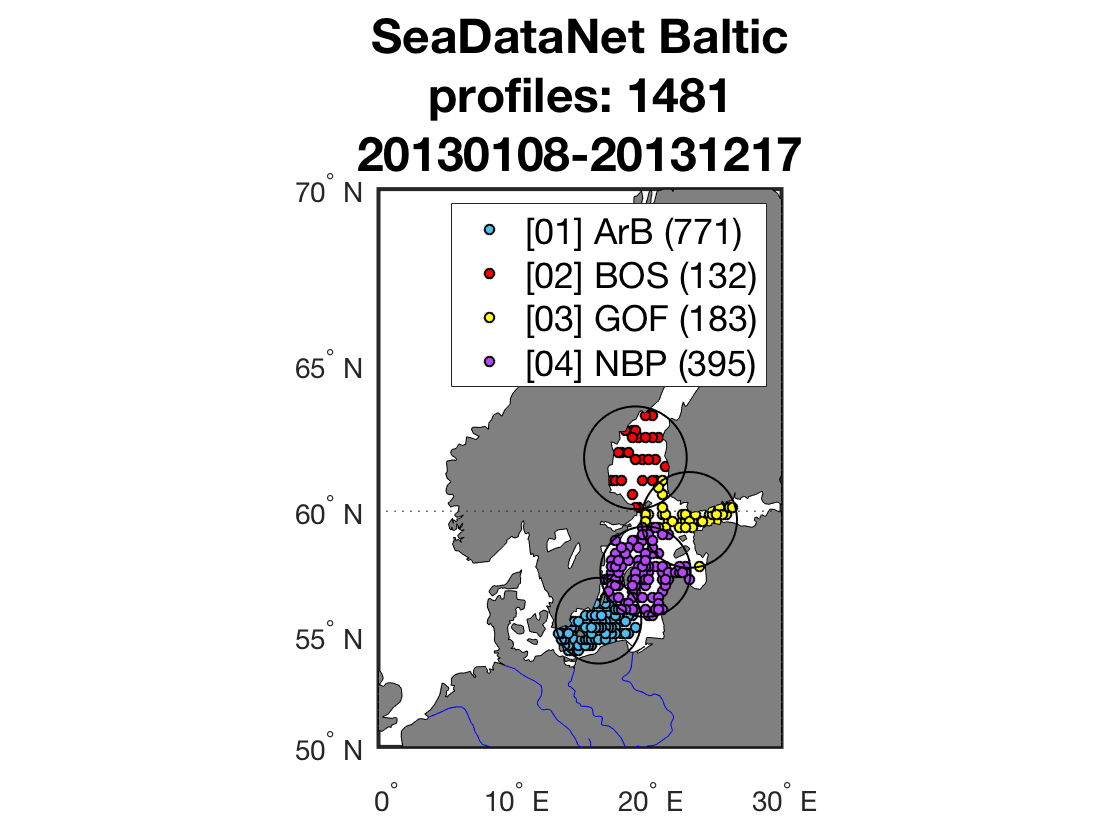


lg = legend(h1,SREG_str3{:},'fontsize',18);

title({...
    ['SeaDataNet ' basin_str];...
    ['profiles: ' num2str(nprof)]
    [time_str1 '-' time_str2] },'fontsize',24);


% Save figure  - output -
fg_name = ['SDN_MAP_REG_' time_str1 '_' time_str2 '.' fg_format];

% Save figure  - output -
folder_this = [folder_figs 'MAPS/'];

if fg_save == 1
    foldercheck_raf(folder_this); %! make folder_figs
end

fg_name = [folder_this fg_name];

% check fn existence
fg_exist = exist(fg_name,'file');
if fg_save == 1 && fg_exist == 0
    save_raf(gcf,fg_name,fg_format); close
end

## [3] TIME SERIES

## [3.1] TIME SERIES SDN SALINITY IN EACH REGION

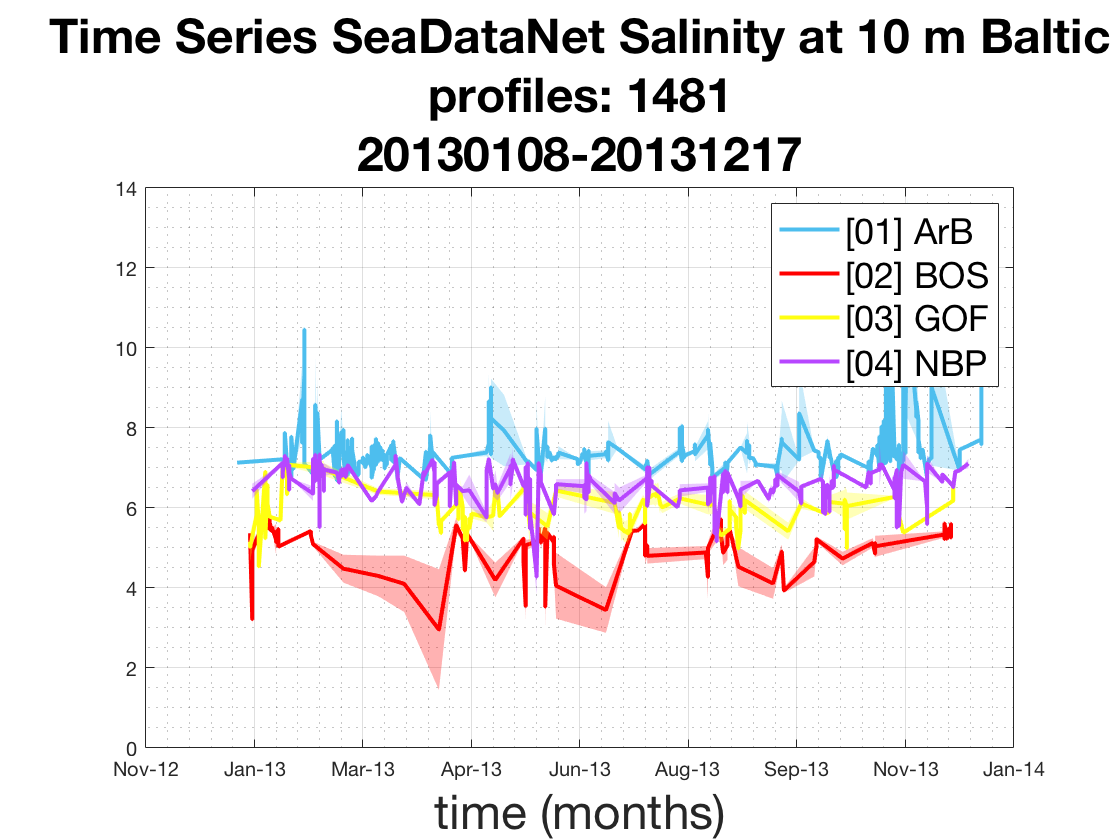

time1 = nanmin(time_sreg_irange(:));
time2 = nanmax(time_sreg_irange(:));

time_str1 = datestr(time1,'yyyymmdd');
time_str2 = datestr(time2,'yyyymmdd');


nprof = sum ((~isnan(lon_sreg_irange(:))) & (~isnan(lat_sreg_irange(:))));


% value from 0 (trasparent) to 1 (opaque) (type help boundedline)
shade_transparent = 0.30;

for nn = 1: length(SREG_str1)
    if nn == 1; figure (22); clf; hold on; end
    
    X = time_sreg_irange(:,nn);
    Y = SALT10_mean_sreg_irange(:,nn);
    Z = SALT10_std_sreg_irange(:,nn);
    
    ind = isnan(X) | isnan(Y) | isnan(Z);
    
    X(ind) = [];
    Y(ind) = [];
    Z(ind) = [];
    
    h1(nn) = plot(X,Y,'-','color',ColorMarker_sreg(nn,:),'linewidth',2); 
    hold all
    
    hold on
    [h2(nn), hp(nn)] = boundedline(X,Y,Z,...
        'alpha','orientation', 'vert' ,...
        'transparency' , shade_transparent);
    hold all
    
    set(h2(nn),'linewidth',2,'color',ColorMarker_sreg(nn,:));
    
    hp(nn).FaceColor =  ColorMarker_sreg(nn,:); % set the color of the shading

     
end

lg = legend(h2,SREG_str1{:},'fontsize',18);


title({...
    ['Time Series SeaDataNet Salinity at 10 m ' basin_str];...
    ['profiles: ' num2str(nprof)]
    [time_str1 '-' time_str2] },'fontsize',24);


grid on 
grid minor
box on

datetick('x','mmm-yy','keeplimits','keepticks')
xlabel('time (months)','fontsize',24);

## [2.5.2] TIMESERIES: ALL-SSS at ALL-float location

Compare each product to Salinity Argo 10-m and to Argo [0-10m] average

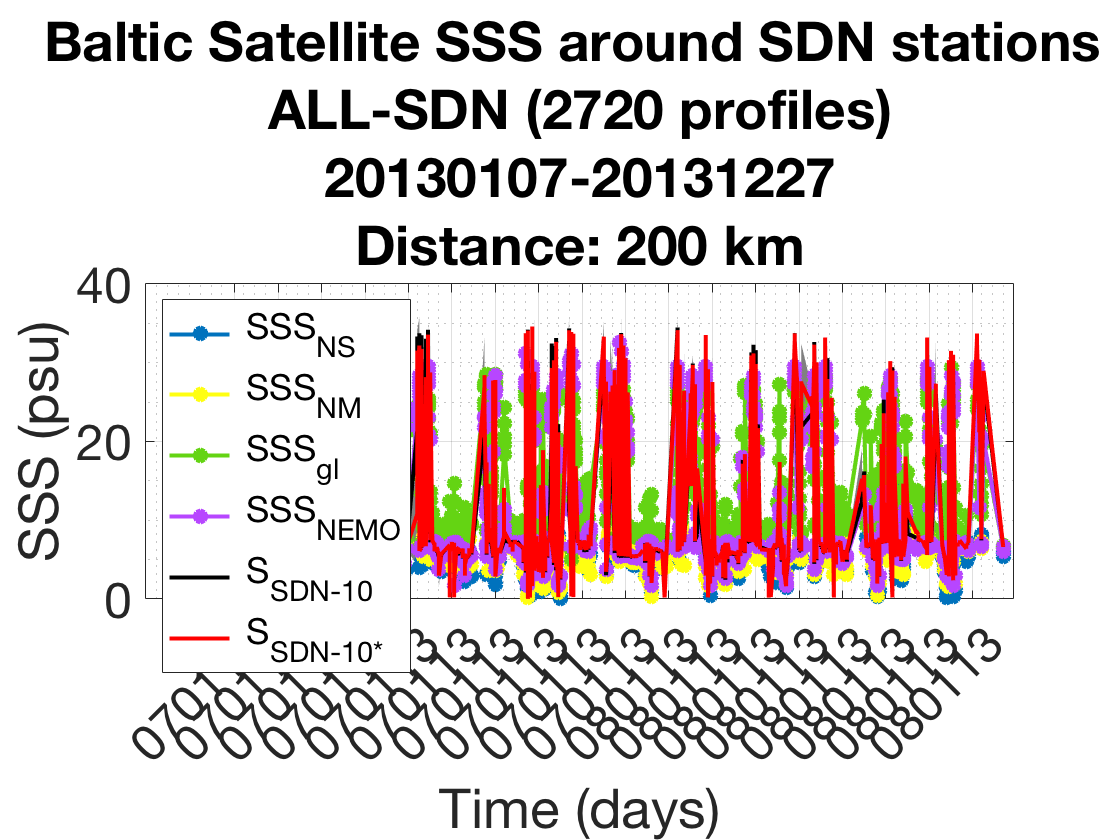

% string product name
PRODS = {...
    ' SSS_{NS}',' SSS_{NM}',' SSS_{gl}',...
    ' SSS_{NEMO}', ' S_{SDN-10}',' S_{SDN-10*}'};

make_plot = 1;

if make_plot == 1
    % Get more colors: type 'uisetcolor'
    color_lines = [...
        0    0.4471    0.7412;...
        1.0000    1.0000    0.0667;...
        0.3922    0.8314    0.0745;...
        0.7176    0.2745    1.0000;...
        0.9294    0.6941    0.1255;...
        1.0000    0.0745    0.6510];
    
    nprof = length(time_irange);
    
    X = time_irange;
    time_line = X(1):20:X(end);
    time_line_diff = diff(time_line);
    
    time_str1 = datestr(X(1),'yyyymmdd');
    time_str2 = datestr(X(end),'yyyymmdd');
    
    Y_beta1 = sss_ns_irange_mn(:);
    Y_beta2 = sss_nm_irange_mn(:);
    Y_beta3 = sss_gl_irange_mn(:);
    Y_beta4 = sss_model_irange_mn(:);
    Y_beta5 = SALT10_point(:);
    Y_beta6 = SALT10_mean(:);
    
    Y_beta1 (Y_beta1 == 0) = NaN;
    Y_beta2 (Y_beta2 == 0) = NaN;
    Y_beta3 (Y_beta3 == 0) = NaN;
    Y_beta4 (Y_beta4 == 0) = NaN;
    Y_beta5 (Y_beta5 == 0) = NaN;
    Y_beta6 (Y_beta6 == 0) = NaN;
    
    % ==========================
    figure
    [hl, hp] = boundedline(X,SALT10_mean(:),SALT10_std(:),'-k',...
        'transparency',0.5);
    
    hold on
    
    h1 = plot(X,Y_beta1,'-o','linewidth',2,'color',color_lines(1,:),...
        'MarkerFaceColor',color_lines(1,:));
    h2 = plot(X,Y_beta2,'-o','linewidth',2,'color',color_lines(2,:),...
        'MarkerFaceColor',color_lines(2,:));
    h3 = plot(X,Y_beta3,'-o','linewidth',2,'color',color_lines(3,:),...
        'MarkerFaceColor',color_lines(3,:));
    h4 = plot(X,Y_beta4,'-o','linewidth',2,'color',color_lines(4,:),...
        'MarkerFaceColor',color_lines(4,:));
    h5 = plot(X,Y_beta5,'-k','linewidth',2);
    h6 = plot(X,Y_beta6,'-r','linewidth',2);
    
    xlabel ('Time (days)','fontsize',20)
    ylabel ('SSS (psu)','fontsize',20)
    
    grid on
    grid minor
    box on
    
    h = findobj(gca, 'type', 'text');
    set(h,'FontSize',25);
    set(h,'VerticalAlignment', 'middle');
    set(gca,'FontSize',25);
    
    xticks(time_line)
    xticklabels(datestr(time_irange,'ddmmyy'))
    xtickangle(45)
    
    lg = legend([h1,h2,h3,h4,h5,h6],PRODS,...
        'fontsize',18,'location','NorthWest');
    
    title({...
        [basin_str ' Satellite SSS around SDN stations '];...
        ['ALL-SDN (' num2str(nprof) ' profiles)'];...
        [time_str1 '-' time_str2]
        ['Distance: ' num2str(r) ' km']});
    
    fg_name = [...
        'ar_PLAT#ALL' ...
        '_SDN2SAT_SSS_TIMESERIES_'...
        time_str1 '_' time_str2...
        '_R' num2str(r) 'KM.'...
        fg_format];
    
    % Save figure  - output -
    folder_this = [folder_figs 'TIMESERIES/SSS/'];
    
    if fg_save == 1
        foldercheck_raf(folder_this); %! make folder_figs
    end
    
    fg_name = [folder_this fg_name];
    
    % check fn existence
    fg_exist = exist(fg_name,'file');
    
    if fg_save == 1 && fg_exist == 0
        save_raf(gcf,fg_name,fg_format); close
    end
end

## [2.5.4] TIMESERIES: ALL-dSSS at ALL-float location

[dSSS = Argo - Satellite (NS and NM)]

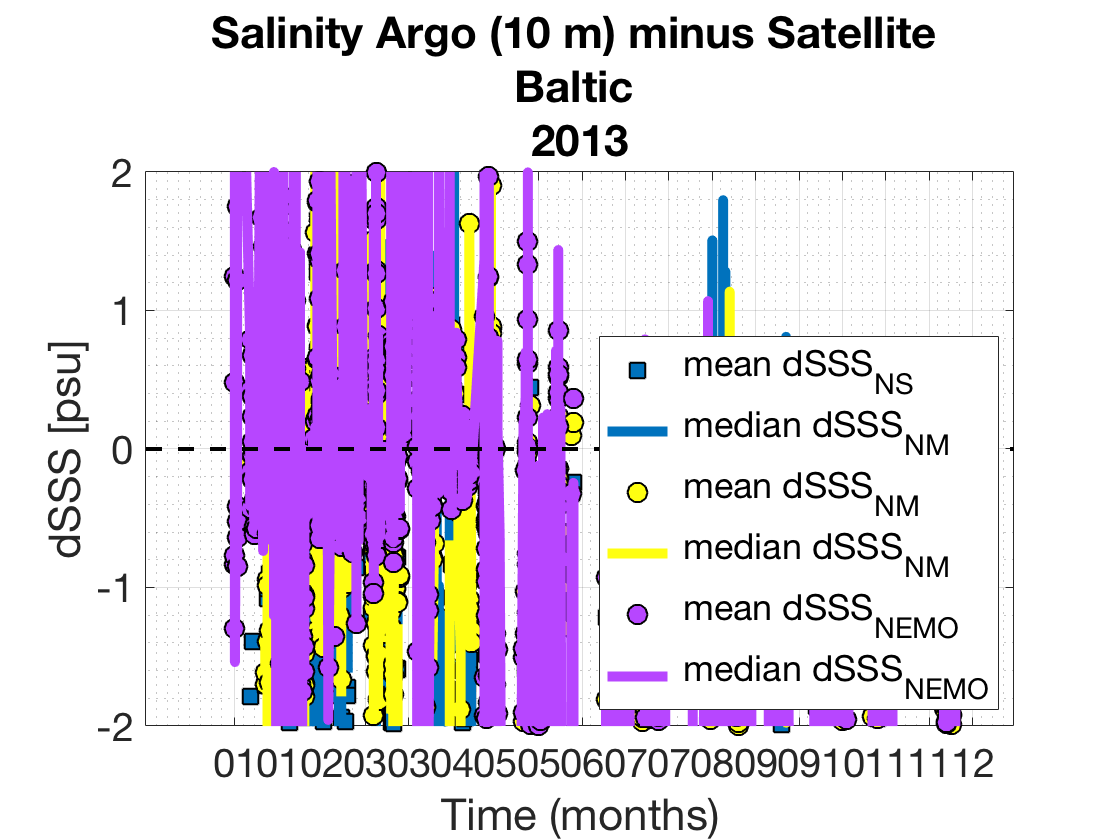

% number of xtick
time_line = time_irange(1):20:time_irange(end);
time_line_diff = diff(time_line);

STATS_vars = {...
    ' mean dSSS_{NS}',' median dSSS_{NM}',...
    ' mean dSSS_{NM}',' median dSSS_{NM}',...
    ' mean dSSS_{NEMO}',' median dSSS_{NEMO}'};

X = time_irange;

Y1_mean = dSSS_ns_irange_mean;
Y2_mean = dSSS_nm_irange_mean;
Y3_mean = dSSS_model_irange_mean;

Y1_median = dSSS_ns_irange_median;
Y2_median = dSSS_nm_irange_median;
Y3_median = dSSS_model_irange_median;


figure (25); clf; hold on

h1 = plot(X,Y1_mean,'ks','MarkerFaceColor',color_lines(1,:),'MarkerSize',10); hold on
h2 = plot(X,Y1_median,'-','color',color_lines(1,:),'LineWidth',5);
h3 = plot(X,Y2_mean,'ko','MarkerFaceColor',color_lines(2,:),'MarkerSize',10); hold on
h4 = plot(X,Y2_median,'-','color',color_lines(2,:),'LineWidth',5);
h5 = plot(X,Y3_mean,'ko','MarkerFaceColor',color_lines(4,:),'MarkerSize',10); hold on
h6 = plot(X,Y3_median,'-','color',color_lines(4,:),'LineWidth',5);


plot(xlim, [0 0],'k--','linewidth',2)

lg = legend([h1,h2,h3,h4,h5,h6],STATS_vars{:},...
    'fontsize',18,'location','SouthEast');

ylim([-2 2])

grid on
grid minor
box on

set(gca,'FontSize',20)

xticks(time_line)
xticklabels(datestr(time_line,'mm'))
% xtickangle(45)

xlabel ('Time (months)','fontsize',20)
ylabel ('dSSS [psu]','fontsize',20)

title({['Salinity Argo (10 m) minus Satellite '],...
    'Baltic ',...
    num2str(iyear)})


% Save figure  - output -
fg_name = ['SDN_'...
    datestr(time_irange(1),'yyyymmdd') '_'....
    datestr(time_irange(end),'yyyymmdd') '_TIMESERIES_dSSS' ...
    '.'  fg_format];

% Save figure  - output -
folder_this = [folder_figs 'TIMESERIES/dSSS/'];

if fg_save == 1
    foldercheck_raf(folder_this); %! make folder_figs
end

fg_name = [folder_this fg_name];

% check fn existence
fg_exist = exist(fg_name,'file');

if fg_save == 1 && fg_exist == 0
    save_raf(gcf,fg_name,fg_format); close
end

## [3] BOXPLOTS

## [2.1] boxplots: ALL SDN data versus Satellite data (at SDN location)

shall we use the median of SSS to be compared againts

make_plot = 0; % flag to make plot [1], or not [0]
if make_plot == 1
    % string product name
    PRODS = {...
        'SSS_{NS}','SSS_{NM}','SSS_{gl}',...
        'SSS_{NEMO}'};
    
    
    NPROFS = length(time_irange);
    
    for nn = 1:NPROFS
        
        this_platform = time_irange(nn);
        
        ind = find(time_irange == this_platform);
        
        nprof = length(ind);
        
        time_this = time_irange(ind);
        
        time_str1 = datestr(time_this(1),'yyyymmdd');
        time_str2 = datestr(time_this(end),'yyyymmdd');
        
        
        X_beta = sss_ns_irange(:,ind);
        Y_beta = sss_nm_irange(:,ind);
        Z_beta = sss_gl_irange(:,ind);
        T_beta = sss_model_irange(:,ind);
        
        X_beta = X_beta(:);
        Y_beta = Y_beta(:);
        Z_beta = Z_beta(:);
        T_beta = T_beta(:);
        
        X_beta (X_beta == 0) = NaN;
        Y_beta (Y_beta == 0) = NaN;
        Z_beta (Z_beta == 0) = NaN;
        T_beta (T_beta == 0) = NaN;
        
        figure; clf; hold on;
        set(gcf,'DefaultAxesFontSize',24);
        
        bplot = boxplot([X_beta,Y_beta,Z_beta,T_beta],'labels',PRODS);
        
        bp = gca;
        bp.XAxis.TickLabelInterpreter = 'tex';
        
        ylim([0 15]);
        
        ylabel('SSS')
        
        grid on
        grid minor
        
        h = findobj(gca, 'type', 'text');
        set(h,'FontSize',25);
        set(h,'VerticalAlignment', 'middle');
        set(gca,'FontSize',25);
        
        title({...
            [basin_str ' Satellite SSS around SDN station '];...
            ['ID: ' sprintf('%03.0f',nn)  ...
            ' (' num2str(nprof) ' profiles)'...
            ', Distance: ' num2str(r) ' km'];...
            [time_str1 '-' time_str2]});
        
        fg_name = ['SDN_ID#' sprintf('%03.0f',nn) ...
            '_SAT-SSS_BOXPLOT_'...
            time_str1 '_' time_str2...
            '_R' num2str(r) 'KM.'...
            fg_format];
        
        % Save figure  - output -
        folder_this = [folder_figs 'BOXPLOTS/'];
        
        if fg_save == 1
            foldercheck_raf(folder_this); %! make folder_figs
        end
        
        fg_name = [folder_this fg_name];
        
        
        fg_exist = exist(fg_name,'file'); % check fn existence
        
        if fg_save == 1 && fg_exist == 0
            save_raf(gcf,fg_name,fg_format); close
        end
        
    end; clear ind *beta* *exist*
    
end

## [3.2] boxplots: ALL SDN data versus ALL Satellite data

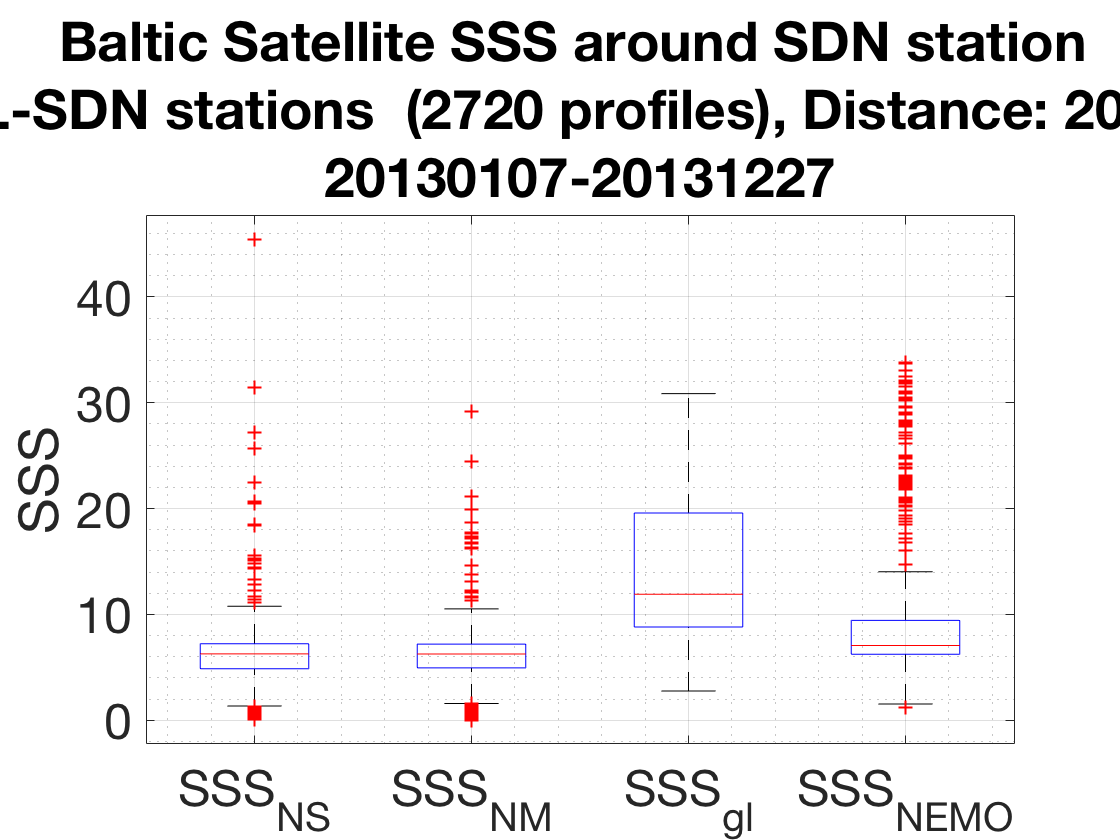

make_plot = 1; % flag to make plot [1], or not [0]
if make_plot == 1
    % string product name
    PRODS = {...
        'SSS_{NS}','SSS_{NM}','SSS_{gl}',...
        'SSS_{NEMO}'};
    
    nprof = length(time_irange);
    
    time_this = time_irange(:);
    
    time_str1 = datestr(time_this(1),'yyyymmdd');
    time_str2 = datestr(time_this(end),'yyyymmdd');
    
    
    X_beta = sss_ns_irange(:);
    Y_beta = sss_nm_irange(:);
    Z_beta = sss_gl_irange(:);
    T_beta = sss_model_irange(:);
    
    X_beta = X_beta(:);
    Y_beta = Y_beta(:);
    Z_beta = Z_beta(:);
    T_beta = T_beta(:);
    
    X_beta (X_beta == 0) = NaN;
    Y_beta (Y_beta == 0) = NaN;
    Z_beta (Z_beta == 0) = NaN;
    T_beta (T_beta == 0) = NaN;
    
    figure; clf; hold on;
    set(gcf,'DefaultAxesFontSize',24);
    
    bplot = boxplot([X_beta,Y_beta,Z_beta,T_beta],'labels',PRODS);
    
    bp = gca;
    bp.XAxis.TickLabelInterpreter = 'tex';
    
    %ylim([0 40]);
    
    ylabel('SSS')
    
    grid on
    grid minor
    
    h = findobj(gca, 'type', 'text');
    set(h,'FontSize',25);
    set(h,'VerticalAlignment', 'middle');
    set(gca,'FontSize',25);
    
    title({...
        [basin_str ' Satellite SSS around SDN station '];...
        ['ALL-SDN stations  (' num2str(nprof) ' profiles)'...
        ', Distance: ' num2str(r) ' km'];...
        [time_str1 '-' time_str2]});
    
    fg_name = ['SDN_ALL'...
        '_SAT-SSS_BOXPLOT_'...
        time_str1 '_' time_str2...
        '_R' num2str(r) 'KM.'...
        fg_format];
    
    % Save figure  - output -
    folder_this = [folder_figs 'BOXPLOTS/'];
    
    if fg_save == 1
        foldercheck_raf(folder_this); %! make folder_figs
    end
    
    fg_name = [folder_this fg_name];
    
    
    fg_exist = exist(fg_name,'file'); % check fn existence
    
    if fg_save == 1 && fg_exist == 0
        save_raf(gcf,fg_name,fg_format); close
    end
    
end; clear ind *beta* *exist*

## [2.6] TAYLOR DIAGRAMS

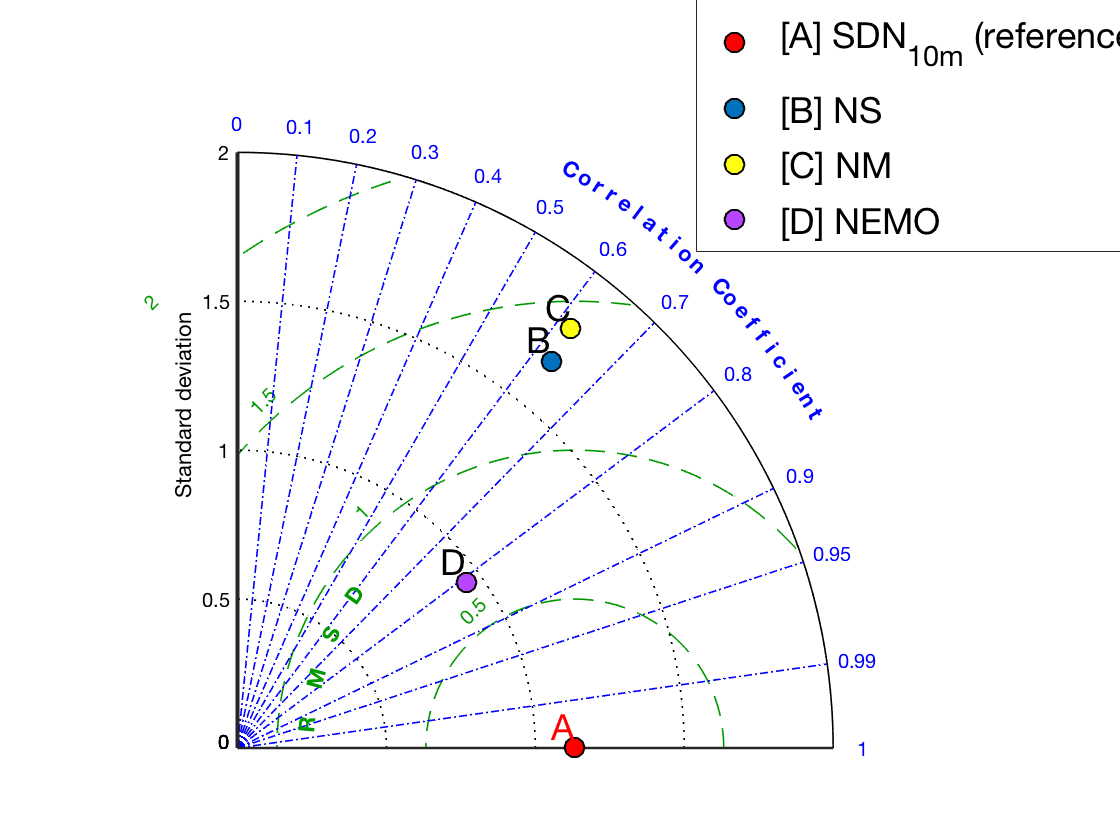

% Compute stats to include in Taylor diagram using Argo_10m 
% (averaged surface) as the reference measure 
% (use function: 'allstats')
% TAYLOR diagrram inputs:
%	[1] STDs: Standard deviations
%	[2] RMSs: Centered Root Mean Square Difference 
%	[3] CORs: Correlation



X_ref = SALT10_mean; % reference salinity

Y1 = sss_nm_irange_mn;
Y2 = sss_ns_irange_mn;
Y3 = sss_model_irange_mn;

ind = ~isnan(X_ref) & ~isnan(Y1) & ~isnan(Y2) & ~isnan(Y3);

X_ref = X_ref(ind);
Y1 = Y1(ind);
Y2 = Y2(ind);
Y3 = Y3(ind);

% =========================
Y1_STATS = allstats(X_ref,Y1);
Y2_STATS = allstats(X_ref,Y2);
Y3_STATS = allstats(X_ref,Y3);

X_ref_STATS = Y1_STATS(:,1);

Y1_STATS = Y1_STATS(:,2);
Y2_STATS = Y2_STATS(:,2);
Y3_STATS = Y3_STATS(:,2);

% standard deviation
n = 2; 
STD_ALL = [...
    X_ref_STATS(n)...
    Y1_STATS(n)...
    Y2_STATS(n)...
    Y3_STATS(n)]; clear n

% Root Mean Square
n = 3; 
RMS_ALL = [...
    X_ref_STATS(n)...
    Y1_STATS(n)...
    Y2_STATS(n)...
    Y3_STATS(n)]; clear n

% Correlation
n = 4; 
CORR_ALL = [...
    X_ref_STATS(n)...
    Y1_STATS(n)...
    Y2_STATS(n)...
    Y3_STATS(n)]; clear n

% =================
figure
% output taylor
% hp: handle for each point
% ht: handle for each text
% axl: handle for axis
[hp ht axl] = taylordiag(STD_ALL,RMS_ALL,CORR_ALL);

marker_size = 10;

set(hp(1),'marker','o','MarkerEdgeColor','k',...
    'MarkerFaceColor','r','MarkerSize',marker_size)
set(hp(2),'marker','o','MarkerEdgeColor','k',...
    'MarkerFaceColor',color_lines(1,:),'MarkerSize',marker_size)
set(hp(3),'marker','o','MarkerEdgeColor','k',...
    'MarkerFaceColor',color_lines(2,:),'MarkerSize',marker_size)
set(hp(4),'marker','o','MarkerEdgeColor','k',...
    'MarkerFaceColor',color_lines(4,:),'MarkerSize',marker_size)


set(ht(1),'color','r','fontsize',18,'verticalalignment','bottom')
set(ht(2),'color','k','fontsize',18)
set(ht(3),'color','k','fontsize',18)
set(ht(4),'color','k','fontsize',18)

lg = legend(hp,{' [A] SDN_{10m} (reference)',' [B] NS',' [C] NM',' [D] NEMO'},...
    'Location','NorthEastOutside','fontsize',18);

% make legend square bigger 
% (https://uk.mathworks.com/matlabcentral/answers/420941-how-can-i-enlarge-the-height-of-legend-box)
lg.Position(1) = 0.80; % move legend left/right [0-1]
lg.Position(2) = 0.70; % move legend down/up [0-1] 
lg.Position(3) = 0.05; % move text in legend left/right [0-1] 
lg.Position(4) = 0.30; % increase/decrease legend box [0-1] 



% Save figure  - output -
fg_name = ['SDN_'...
    datestr(time_irange(1),'yyyymmdd') '_'....
    datestr(time_irange(end),'yyyymmdd') '_TAYLOR_SSS' ...
    '.'  fg_format];

% Save figure  - output -
folder_this = [folder_figs 'TAYLOR/SSS/'];

if fg_save == 1
    foldercheck_raf(folder_this); %! make folder_figs
end

fg_name = [folder_this fg_name];

% check fn existence
fg_exist = exist(fg_name,'file');

if fg_save == 1 && fg_exist == 0
    save_raf(gcf,fg_name,fg_format); close
end







% END-OF-SCRIPT